userpath("reset")
addpath(genpath('C:\Users\haneo\Documents\GitHub\NetOTC'))

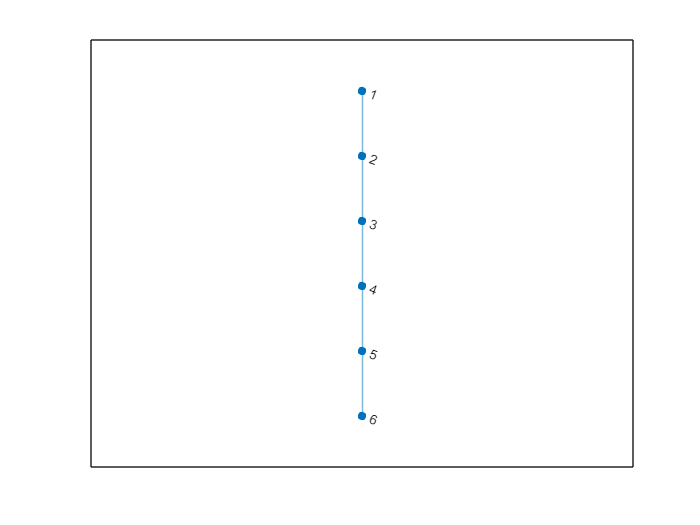

n = 6;
A1 = zeros(n, n);
for row=1:n-1
    A1(row, row+1) = 1;
    A1(row+1, row) = 1;
end

perm = randperm(n);
A2 = A1(perm,perm);

figure(1);
G1 = graph(A1);
plot(G1);

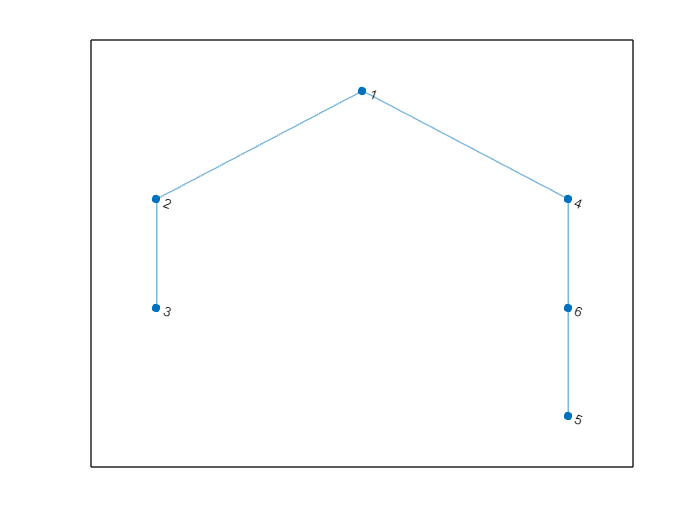

figure(2);
G2 = graph(A2);
plot(G2);


% Get transition matrices
P1 = A1 ./ sum(A1, 2);
P2 = A2 ./ sum(A2, 2);

% Get distributions
stat_dist1 = approx_stat_dist(P1, 100)';
stat_dist2 = approx_stat_dist(P2, 100)';
unif_dist1 = ones(n,1)/n;
unif_dist2 = ones(n,1)/n;

% Get cost function
c = get_degree_cost(A1, A2);

[otc_distance, gotc, otc_alignment]  = exact_otc(P1, P2, c);
otc_alignment;

[~, otc_perm] = max(otc_alignment(1:n,:));

otc_alignment

otc_alignment =          0         0    0.1000         0         0         0
         0    0.2000         0         0         0         0
    0.2000         0         0         0         0         0
         0         0         0    0.2000         0         0
         0         0         0         0         0    0.2000
         0         0         0         0    0.1000         0


otc_perm

otc_perm =      3     2     1     4     6     5


perm

perm =      4     5     6     3     1     2


check_isomorphism(otc_perm, A1, A2)

ans = 0

cnt = 0;
for itr = 1:30
    itr
    n1 = 12; % number of nodes in the candy part
    n2 = 3; % number of nodes in the stick part
    n = n1+n2;
    p = 0.5;
    
    % Construct adjacency matrices
    % [~,A1] = stochastic_block_model([n1], [p]);
    % A1 = triu(A1,1);
    % A1 =  
    % for row=1:(n1-1)
    %     if A1(row,row+1) == 0
    %         A1(row,row+1) = 1;
    %     end
    % end
    A1 = zeros(n1);
    for row=1:(n1-1)
        A1(row,row+1) = 1;
    end
    A1(1,n1) = 1;
    A1 = A1 + A1.';
    
    A2 = zeros(n2,n2);
    for row=1:(n2-1)
        A2(row,row+1) = 1;
    end
    A2 = A2 + A2.';
    
    A = zeros(n,n);
    A(1:n1,1:n1) = A1;
    A(n1+1:n,n1+1:n) = A2;
    A(n1,n1+1) = 1;
    A(n1+1,n1) = 1;
    A1 = A;
    
    % Random permutation
    perm = randperm(n);
    A2 = A1(perm,perm);
    
    % Get transition matrices
    P1 = A1 ./ sum(A1, 2);
    P2 = A2 ./ sum(A2, 2);
    
    % Get distributions
    stat_dist1 = approx_stat_dist(P1, 100)';
    stat_dist2 = approx_stat_dist(P2, 100)';
    unif_dist1 = ones(n,1)/n;
    unif_dist2 = ones(n,1)/n;
    
    % Get cost function
    c = get_degree_cost(A1, A2);
    
    [otc_distance, gotc, otc_alignment]  = exact_otc(P1, P2, c);
    otc_alignment;
    
    [~, otc_perm] = max(otc_alignment(1:n,:));
    cnt = cnt+ isequal(otc_perm, perm);
end

itr = 1

itr = 2

itr = 3

itr = 4

itr = 5

itr = 6

itr = 7

itr = 8

itr = 9

itr = 10

itr = 11

itr = 12

itr = 13

itr = 14

itr = 15


perm
otc_perm
otc_distance